## Grating Stimulus Setup

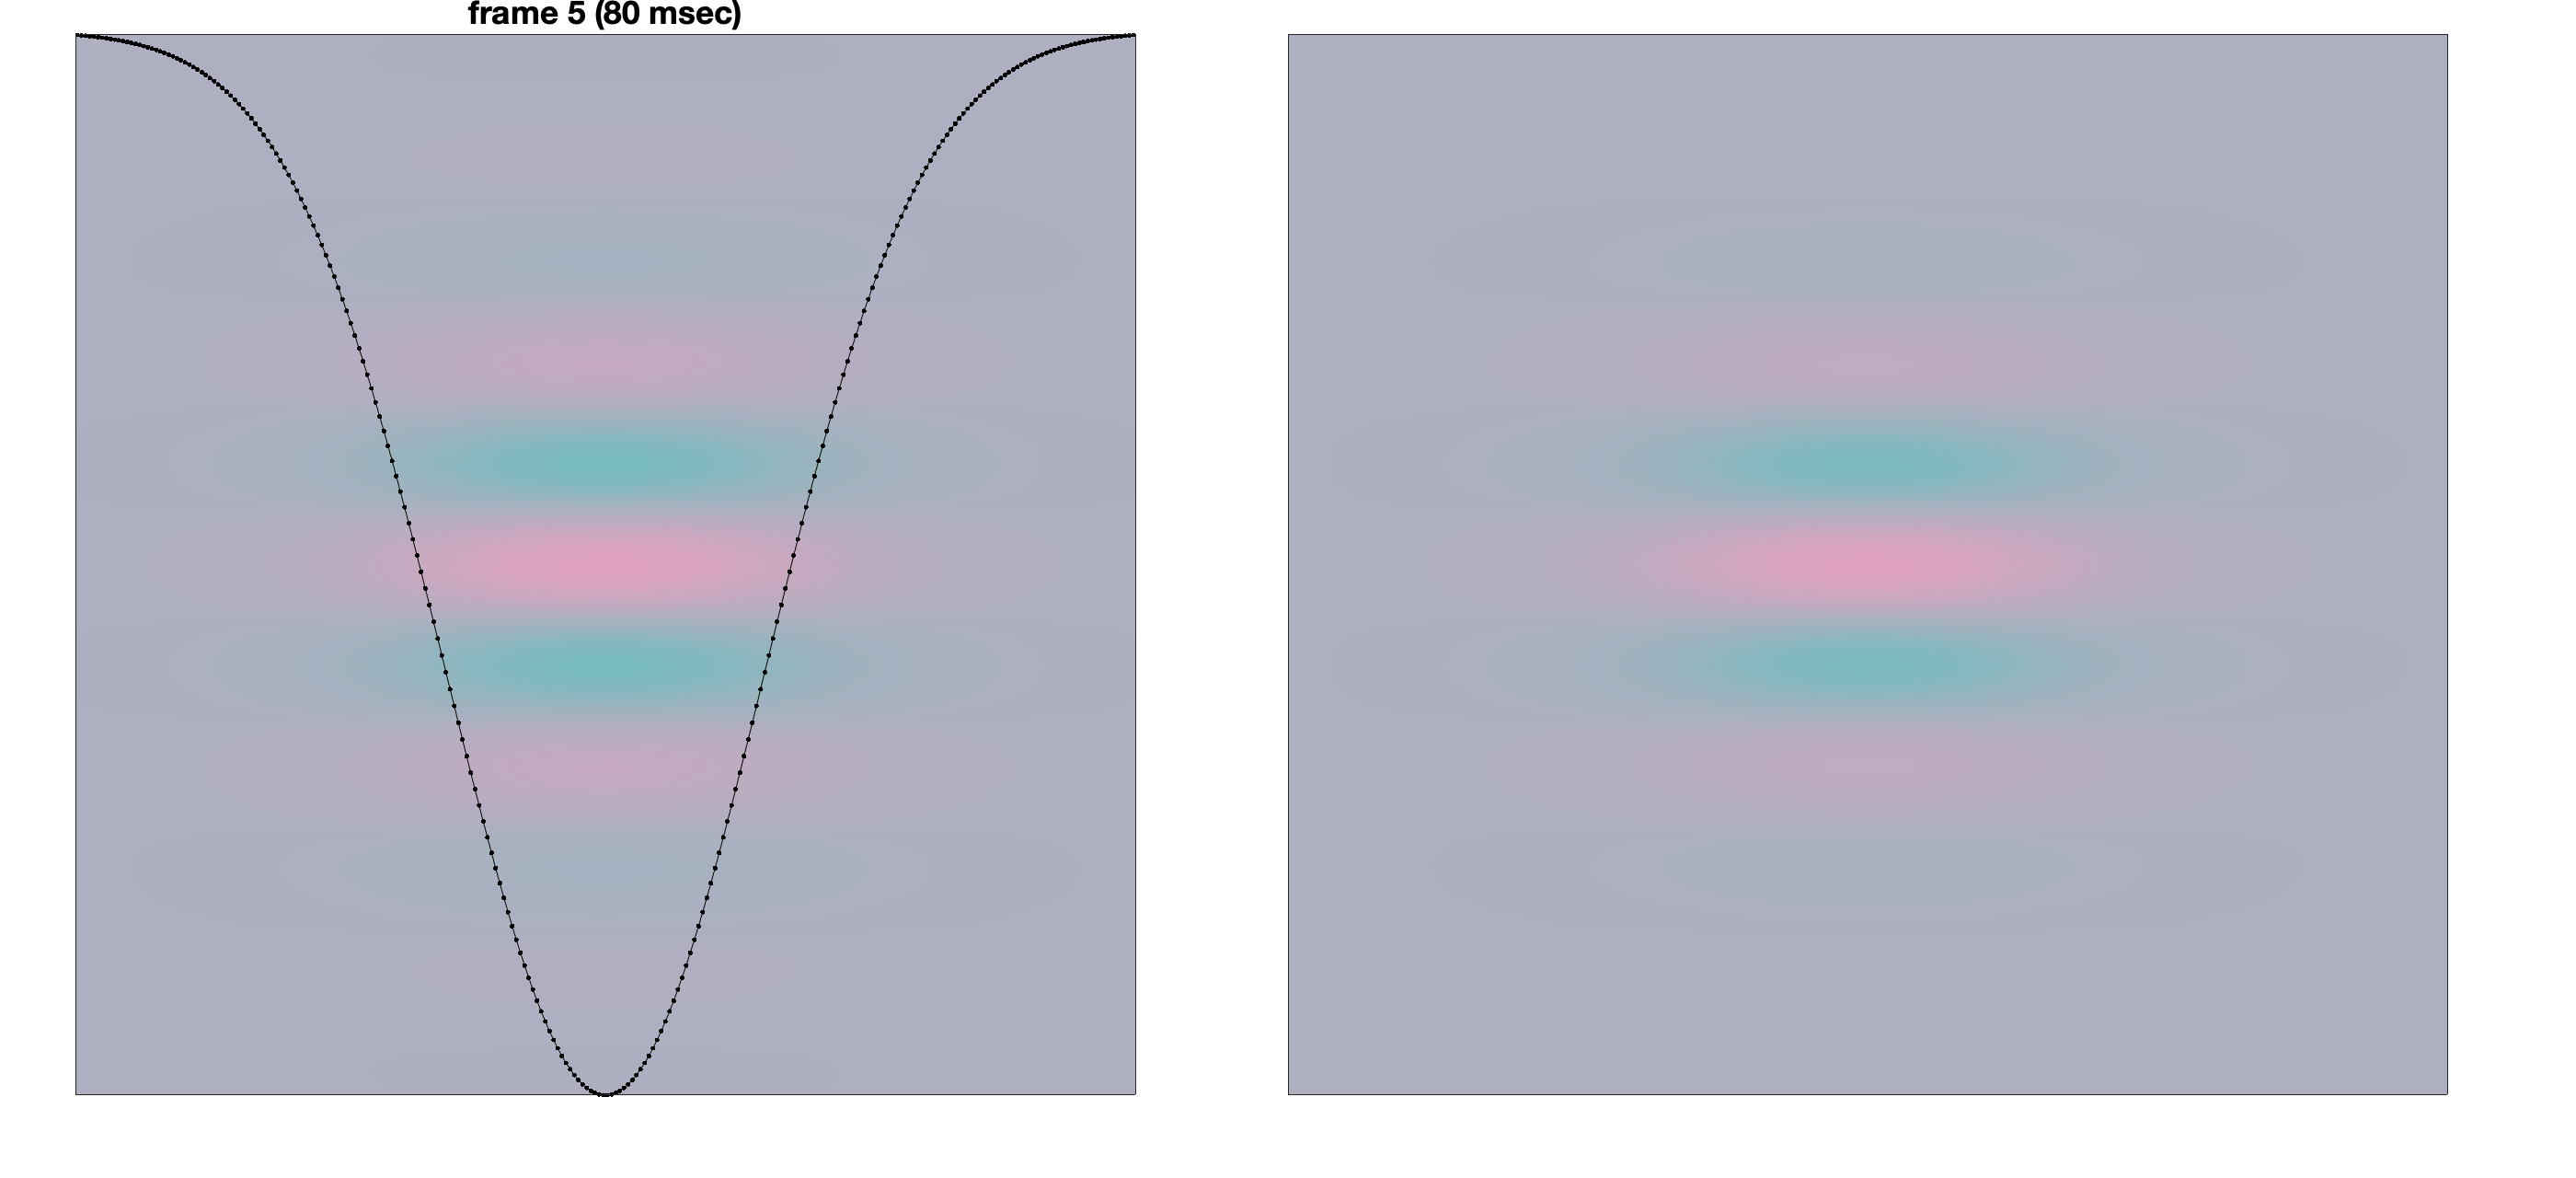

sceneComputeFunction = @sceGrating;
sceneParams = struct(...
    'viewingDistanceMeters', 0.50, ...              % display: viewing distance
    'bitDepth',20, ...                             % display: length of LUT
    'gammaTableExponent',2, ...                  % display: shape of LUT, 1 = Linear
    'spectralSupport', 400:10:750, ...              % display: spectral support of the primary SPDs, in nanometers
    'meanLuminanceCdPerM2', 20, ...                 % background: mean luminance, in candellas per meter squared
    'meanChromaticityXY', [0.3 0.32], ...           % background: neutral mean chromaticity
    'coneContrastModulation', [0.09 -0.09 0.0], ... % chromatic direction: LMS cone contrasts [0.09 -0.09 0.0]
    'warningInsteadOfErrorOnOutOfGamut', false, ... % chromatic: whether to throw an error or a warning if out-of-gamut pixels are generated
    'fovDegs',0.5, ...                             % spatial: field of view, in degrees
    'minPixelsNumPerCycle',10, ...                 % spatial: min number of pixels per grating spatial period (to minimize aliasing effects)
    'pixelsNum', 256, ...                           % spatial: desired size of stimulus in pixels - this could be larger depending on the minPixelsNumPerCycle, the SF, and the FOV
    'spatialFrequencyCyclesPerDeg', 10, ...          % spatial: grating spatial freequency, in cycles/deg
    'orientationDegs', 0, ...                       % spatial: grating orientation, in degrees
    'spatialPhaseDegs', 180, ...                     % spatial: grating spatial phase, in degrees
    'spatialPositionDegs', [0.0 0.0], ...           % spatial: center of grating, in degrees
    'spatialModulation', 'harmonic', ...            % spatial: contrast modulation - choose between {'harmonic', 'square'} for sinusoidal/square spatial modulation 
    'spatialModulationDomain', 'cartesian', ...     % spatial: domain of spatial modulation - choose between {'cartesian', 'polar'}
    'spatialEnvelope', 'soft', ...                  % spatial: envelope - choose between {'disk', 'rect', 'soft'}
    'spatialEnvelopeRadiusDegs',0.2/3, ...          % spatial: radius of the spatial envelope, in degs    
    'temporalModulation', 'drifted', ...            % temporal modulation mode: choose between {'flashed', 'drifted', 'counter phase modulated'}
    'temporalModulationParams', struct(...          % temporal: modulation params struct
        'temporalFrequencyHz', 50, ...            %   params relevant to the temporalModulationMode
        'stimDurationTemporalCycles', 5), ...            %   params relevant to the temporalModulationMode
    'frameDurationSeconds', 20/1000 ...            % temporal: frame duration, in seconds
    );
testContrast = 0.7;
theSceneEngine = sceneEngine(sceneComputeFunction, sceneParams);
% Compute the scene sequence
[theSceneSequence, theSceneTemporalSupportSeconds] = theSceneEngine.compute(testContrast);
% theSceneEngine.visualizeSceneSequence(theSceneSequence, theSceneTemporalSupportSeconds);
theSceneEngine.visualizeStaticFrame(theSceneSequence); % ,'frameToVisualize', 1

% % create cone mosaic
% integrationTime = 50;
% theMosaic = cMosaic('sizeDegs', [1, 1] * sceneParams.fovDegs, ...
%             'eccentricityDegs', [0 0], ...
%             'integrationTime', integrationTime / 1000);
% neuralComputeFunction = @nrePhotocurrentsCmosaicEyeMovements;
% customNeuralResponseParams = struct(...
%     'opticsParams',  struct(...
%         'type', 'wvf human', ...
%         'PolansSubject', 10, ...
%         'pupilDiameterMM', 3.0 ...
%     ), ...
%     'eyeMovementsParams', struct(...
%         'driftModel', 'default', ...
%         'durationSeconds', 300/1000, ...
%         'keptResponsesDurationSeconds', 100/1000 ...
%     ), ...
%     'coneMosaicParams', theMosaic);
% % Instantiate a neuralResponseEngine with the custom neural response params
% theNeuralEngine = neuralResponseEngine(neuralComputeFunction, customNeuralResponseParams);

## Stimulus 2

sceneComputeFunction = @sceGrating;
sceneParams = struct(...
    'viewingDistanceMeters', 0.50, ...              % display: viewing distance
    'bitDepth',20, ...                             % display: length of LUT
    'gammaTableExponent',2, ...                  % display: shape of LUT, 1 = Linear
    'spectralSupport', 400:10:750, ...              % display: spectral support of the primary SPDs, in nanometers
    'meanLuminanceCdPerM2', 20, ...                 % background: mean luminance, in candellas per meter squared
    'meanChromaticityXY', [0.3 0.32], ...           % background: neutral mean chromaticity
    'coneContrastModulation', [0.09 -0.09 0.0], ... % chromatic direction: LMS cone contrasts [0.09 -0.09 0.0]
    'warningInsteadOfErrorOnOutOfGamut', false, ... % chromatic: whether to throw an error or a warning if out-of-gamut pixels are generated
    'fovDegs',0.5, ...                             % spatial: field of view, in degrees
    'minPixelsNumPerCycle',10, ...                 % spatial: min number of pixels per grating spatial period (to minimize aliasing effects)
    'pixelsNum', 256, ...                           % spatial: desired size of stimulus in pixels - this could be larger depending on the minPixelsNumPerCycle, the SF, and the FOV
    'spatialFrequencyCyclesPerDeg', 10, ...          % spatial: grating spatial freequency, in cycles/deg
    'orientationDegs', 0, ...                       % spatial: grating orientation, in degrees
    'spatialPhaseDegs', 180, ...                     % spatial: grating spatial phase, in degrees
    'spatialPositionDegs', [0.0 0.0], ...           % spatial: center of grating, in degrees
    'spatialModulation', 'harmonic', ...            % spatial: contrast modulation - choose between {'harmonic', 'square'} for sinusoidal/square spatial modulation 
    'spatialModulationDomain', 'cartesian', ...     % spatial: domain of spatial modulation - choose between {'cartesian', 'polar'}
    'spatialEnvelope', 'soft', ...                  % spatial: envelope - choose between {'disk', 'rect', 'soft'}
    'spatialEnvelopeRadiusDegs',0.2/3, ...          % spatial: radius of the spatial envelope, in degs    
    'temporalModulation', 'drifted', ...            % temporal modulation mode: choose between {'flashed', 'drifted', 'counter phase modulated'}
    'temporalModulationParams', struct(...          % temporal: modulation params struct
        'temporalFrequencyHz', 50, ...            %   params relevant to the temporalModulationMode
        'stimDurationTemporalCycles', 5), ...            %   params relevant to the temporalModulationMode
    'frameDurationSeconds', 20/1000 ...            % temporal: frame duration, in seconds
    );
testContrast = 0;
theSceneEngine = sceneEngine(sceneComputeFunction, sceneParams);
% create cone mosaic
integrationTime = 50;
theMosaic = cMosaic('sizeDegs', [1, 1] * sceneParams.fovDegs, ...
            'eccentricityDegs', [0 0], ...
            'integrationTime', integrationTime / 1000);

Loading cone mosaic data from /Users/qiyuanfeng/Documents/MATLAB/toolboxes/isetbio/isettools/ganglioncells/data/lattices/right_eye_cones_58deg_mosaic.


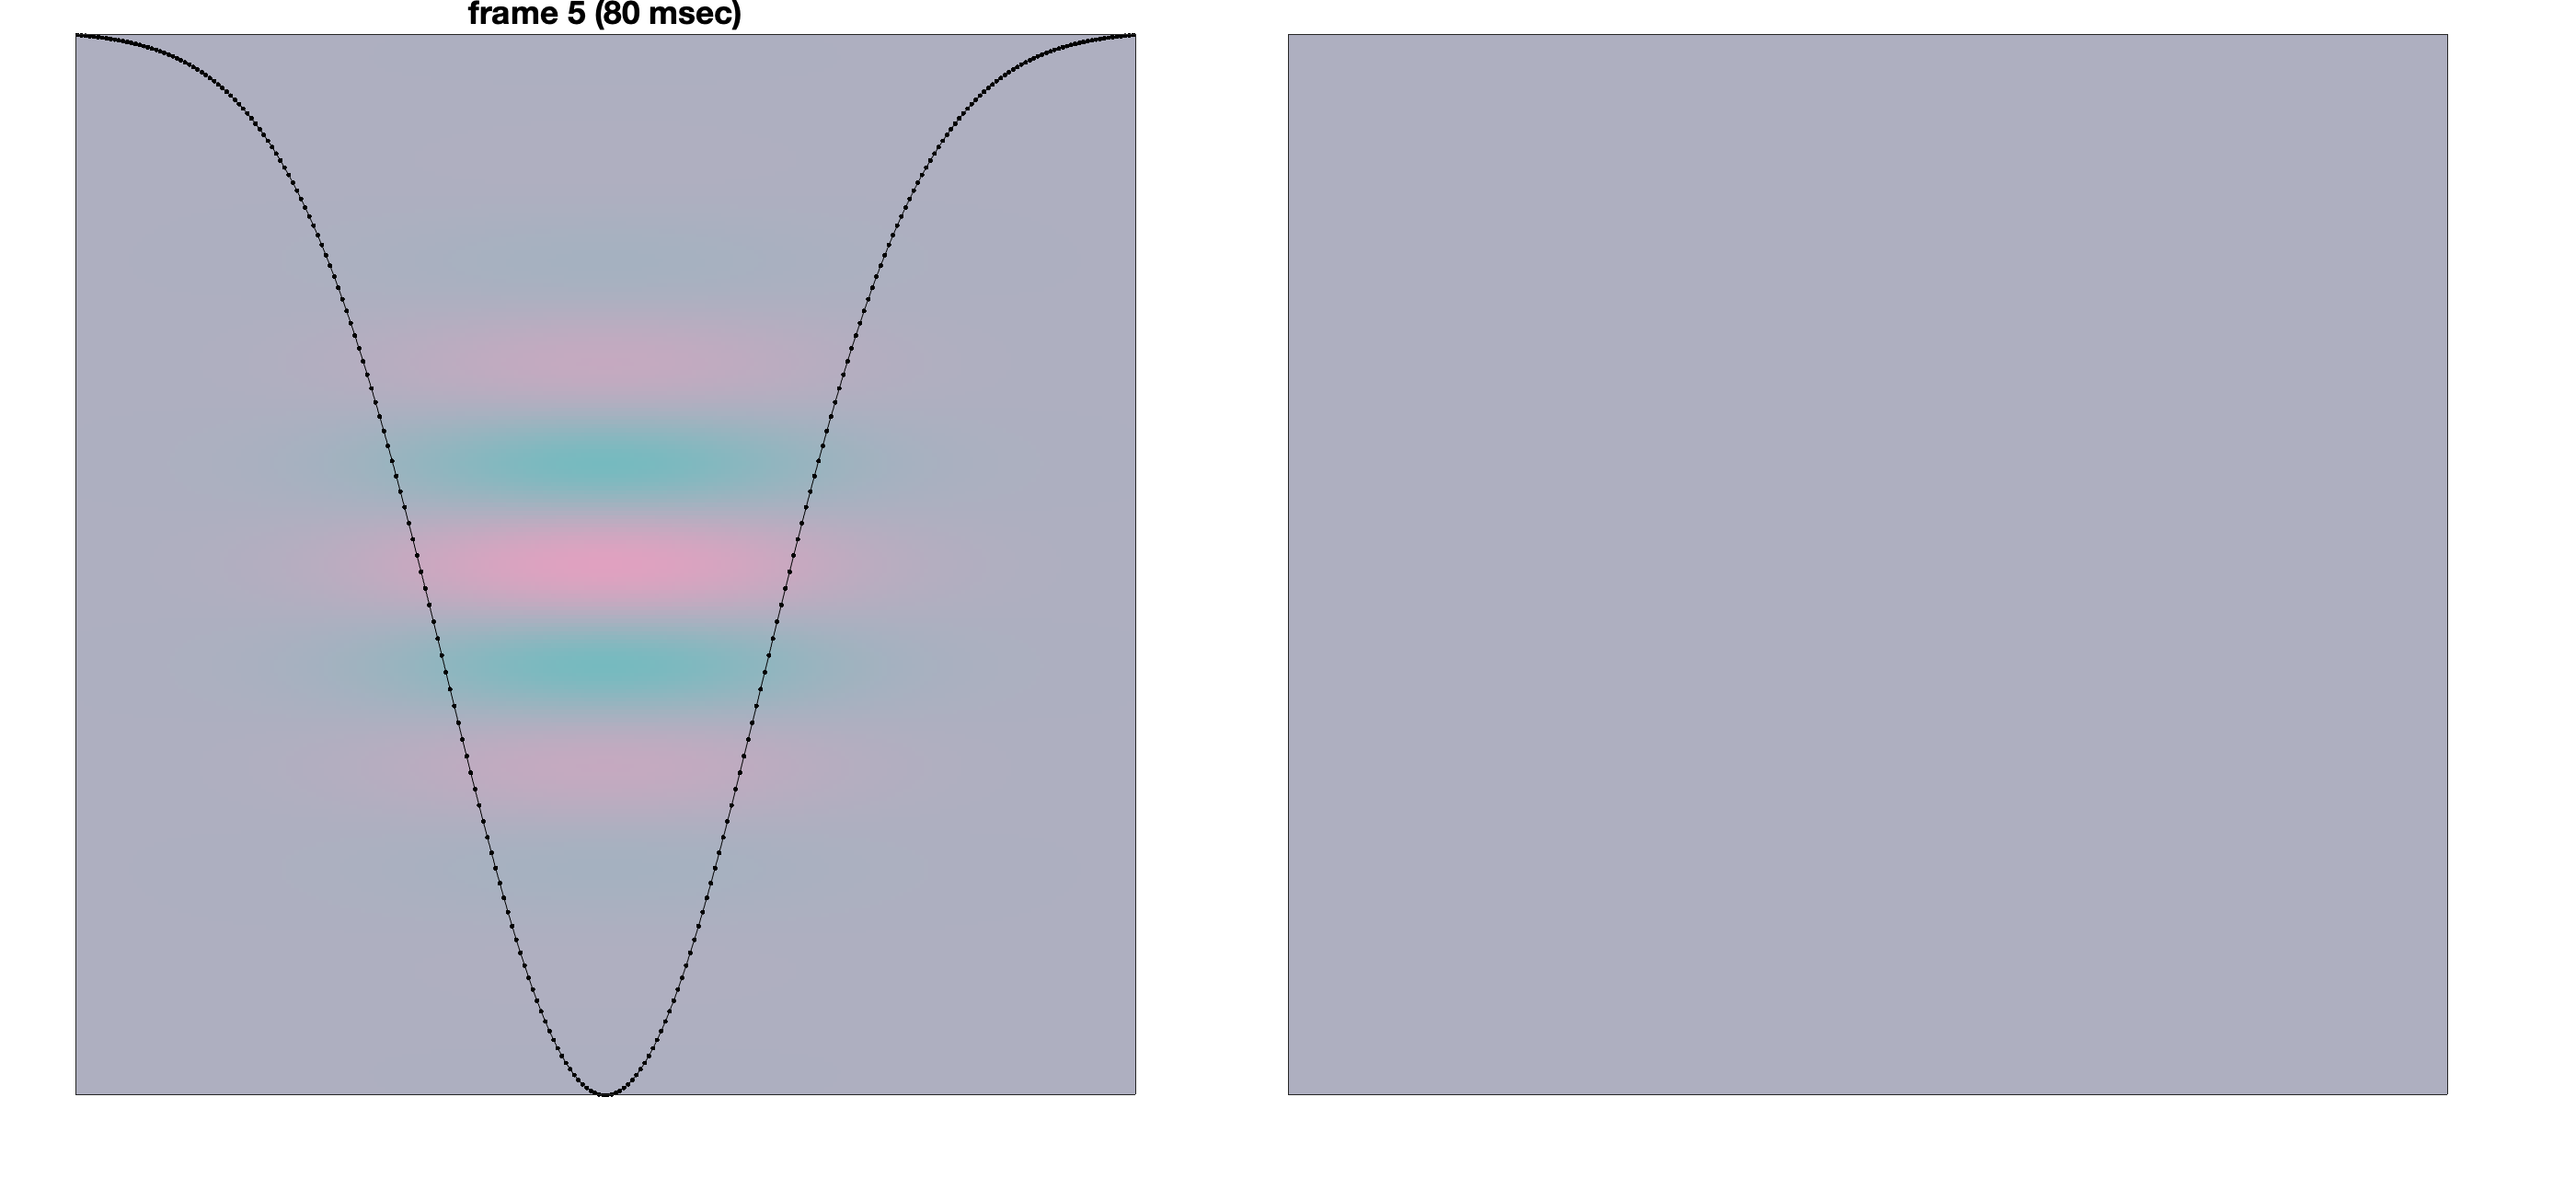

neuralComputeFunction = @nrePhotocurrentsCmosaicEyeMovements;
customNeuralResponseParams = struct(...
    'opticsParams',  struct(...
        'type', 'wvf human', ...
        'PolansSubject', 10, ...
        'pupilDiameterMM', 3.0 ...
    ), ...
    'eyeMovementsParams', struct(...
        'driftModel', 'default', ...
        'durationSeconds', 300/1000, ...
        'keptResponsesDurationSeconds', 100/1000 ...
    ), ...
    'coneMosaicParams', theMosaic);
% Instantiate a neuralResponseEngine with the custom neural response params
theNeuralEngine = neuralResponseEngine(neuralComputeFunction, customNeuralResponseParams);
% Compute the scene sequence
[theSceneSequence, theSceneTemporalSupportSeconds] = theSceneEngine.compute(testContrast);
% theSceneEngine.visualizeSceneSequence(theSceneSequence, theSceneTemporalSupportSeconds);
theSceneEngine.visualizeStaticFrame(theSceneSequence); % ,'frameToVisualize', 1